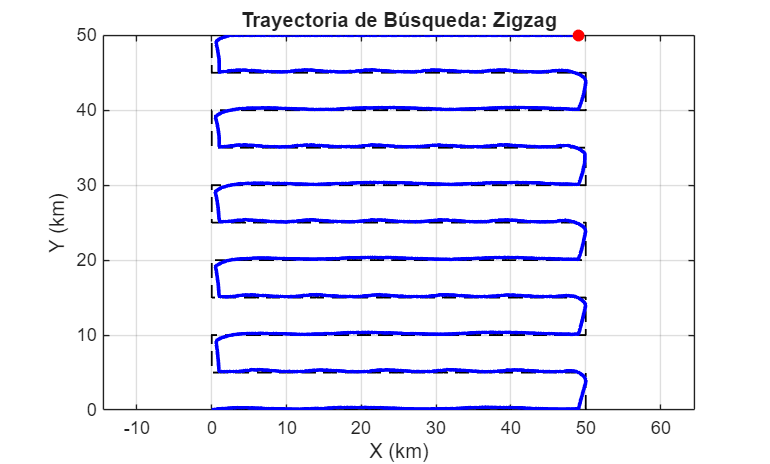

%% Actividad Módulo 3 - Simulación dron

clear; clc; close all;

%% 1. CONFIGURACIÓN GENERAL DEL SISTEMA
mission = "fire"; % Tipo de misión: "fire" o "person"
grid_size = 50; % Tamaño del parque (50x50 km)
dt = 1; % Paso de integración (segundos)
v_max = 0.015; % Velocidad máxima del dron (km/s ≈ 15 m/s)
kp_x = 1; % Ganancia proporcional eje X
kp_y = 1; % Ganancia proporcional eje Y

gps_interval = 15; % Intervalo de actualización del GPS (s)
err_int_max = 0.25; % Error máximo de rastreo interno (+/- km)
err_gps_max = 0.60; % Error máximo del GPS (+/- km), debe ser mayor al interno

% Selección del patrón de cobertura según misión
if mission == "fire"
    detection_size = 5; % Separación entre pasadas del zigzag (5 km)
    wp_tol = 1.0; % Tolerancia para considerar alcanzado el waypoint
else
    detection_size = 3; % Pasadas más densas (3 km)
    wp_tol = 0.6; % Mayor precisión requerida
end

% Parámetros de viento (Disturbios)
V0_wind = 0.005;  % Componente base del viento (km/s)
A_wind = 0.003; % Amplitud de variación del viento (km/s)
T_wind = 900; % Periodo del viento (900 s = 15 min)
omega_wind = 2*pi/T_wind; % Frecuencia angular
gust_std = 0.001; % Desviación estándar de ráfagas aleatorias

%% 2. GENERACIÓN DE WAYPOINTS EN ZIGZAG
xL = 0; % Límite izquierdo del parque
xR = grid_size; % Límite derecho del parque

ys = 0:detection_size:grid_size; % Carriles horizontales en Y

x_wp = []; % Vector de coordenadas X de referencia
y_wp = []; % Vector de coordenadas Y de referencia
t_now = 0; % Tiempo simulado acumulado (s)
step_size = 1; % Separación entre puntos dentro de cada carril

% Construcción del patrón zigzag
for k = 1:length(ys)
    % Alternar dirección en cada carril
    if mod(k,2) == 1 
        % Carril impar: izquierda → derecha
        x_line = (xL:step_size:xR)'; 
    else
        % Carril par: derecha → izquierda
        x_line = (xR:-step_size:xL)'; 
    end
    % Todos los puntos del carril tienen misma coordenada Y
    y_line = ones(size(x_line)) * ys(k); 

    % Agregar carril completo al conjunto de waypoints
    x_wp = [x_wp; x_line];
    y_wp = [y_wp; y_line];
end

%% 3. SIMULACIÓN DEL MOVIMIENTO DEL DRON
x = 0; % Posición inicial en X
y = 0; % Posición inicial en Y
x_hist = []; % Historial de posiciones X
y_hist = []; % Historial de posiciones Y

% Variables para guardar el historial de errores
err_x_hist = []; 
err_y_hist = [];
t_hist = [];

% Variables para el historial del error real de seguimiento
err_tracking_x_hist = [];
err_tracking_y_hist = [];

% Recorrer todos los waypoints generados
for i = 1:length(x_wp)

    x_ref = x_wp(i); % Coordenada objetivo actual X
    y_ref = y_wp(i); % Coordenada objetivo actual Y
    
    % Mientras el dron no esté suficientemente cerca del waypoint
    while sqrt((x_ref - x)^2 + (y_ref - y)^2) > wp_tol

        % MODELO DE ERRORES DE CONEXIÓN Y SENSORES
        % Verificamos si hay conexión GPS (cada 15 segundos)
        if mod(t_now, gps_interval) == 0
            % Error de GPS (Mayor que el interno)
            noise_x = (rand() * 2 - 1) * err_gps_max;
            noise_y = (rand() * 2 - 1) * err_gps_max;
        else
            % Error de rastreo interno (+/- 0.25 km)
            noise_x = (rand() * 2 - 1) * err_int_max;
            noise_y = (rand() * 2 - 1) * err_int_max;
        end
        
        % Posición medida por los sensores (La que "cree" tener el dron)
        x_meas = x + noise_x;
        y_meas = y + noise_y;

        % Calcular y guardar el error real de seguimiento (Posición de referencia vs Posición real)
        ex_true = x_ref - x;
        ey_true = y_ref - y;
        
        err_tracking_x_hist = [err_tracking_x_hist; ex_true];
        err_tracking_y_hist = [err_tracking_y_hist; ey_true];
        
        % Guardar historial de errores para graficar
        err_x_hist = [err_x_hist; noise_x];
        err_y_hist = [err_y_hist; noise_y];
        t_hist = [t_hist; t_now];
        
        % EL CONTROL DEBE USAR LA POSICIÓN MEDIDA, NO LA REAL
        ex = x_ref - x_meas;
        ey = y_ref - y_meas;

        % CONTROL PROPORCIONAL (P)
        
        % Velocidad deseada proporcional al error
        ux = kp_x * ex;
        uy = kp_y * ey;

        % SATURACIÓN DE VELOCIDAD (LÍMITE FÍSICO)

        v_norm = sqrt(ux^2 + uy^2); % Magnitud de velocidad

        if v_norm > v_max
            % Escalar vector velocidad para que no exceda v_max
            ux = (ux / v_norm) * v_max;
            uy = (uy / v_norm) * v_max;
        end
        
        % MODELO DE VIENTO (DISTURBIO EXTERNO)
        % Componente base + oscilación periódica + ráfagas aleatorias
        dx = V0_wind + A_wind*sin(omega_wind*t_now) + gust_std*randn();
        dy = 0.5*V0_wind + 0.5*A_wind*cos(omega_wind*t_now) + gust_std*randn();
        
        % ACTUALIZACIÓN DE POSICIÓN (INTEGRACIÓN EULER)

        x = x + (ux + dx) * dt;
        y = y + (uy + dy) * dt;

        % Limitar posición dentro del parque (0 a 50 km)
        x = max(min(x, grid_size), 0);
        y = max(min(y, grid_size), 0);
        
        % Guardar trayectoria
        x_hist = [x_hist; x];
        y_hist = [y_hist; y];

        % Avanzar tiempo simulado
        t_now = t_now + dt;
    end
end

%% 4. ANIMACIÓN DEL MOVIMIENTO

figure('Color', 'w');

% Dibujar trayectoria de referencia
plot(x_wp, y_wp, 'k--', 'LineWidth', 1); hold on;

% Crear objetos gráficos para animación
hPath = plot(NaN, NaN, 'b', 'LineWidth', 2); % Trayectoria recorrida
hDrone = plot(NaN, NaN, 'ro', 'MarkerFaceColor', 'r'); % Posición actual

% Configuración visual
grid on; 
axis([0 50 0 50]); % Límites del mapa
axis equal; % Escala igual en X y Y

xlabel('X (km)'); 
ylabel('Y (km)');
title('Trayectoria de Búsqueda: Zigzag');

% Animación progresiva
for i = 1:10:length(x_hist)
    set(hPath, 'XData', x_hist(1:i), 'YData', y_hist(1:i));
    set(hDrone, 'XData', x_hist(i), 'YData', y_hist(i));
    drawnow limitrate;
end

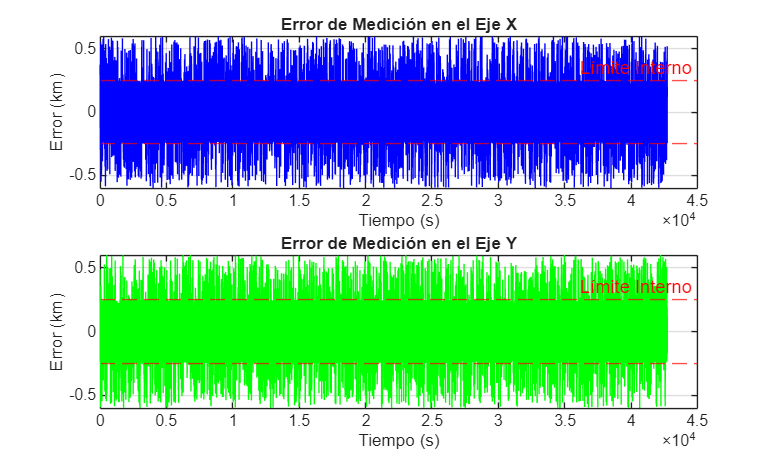


%% GRAFICACION DE ERRORES

figure('Color', 'w', 'Name', 'Análisis de Errores de Medición');

subplot(2,1,1);
plot(t_hist, err_x_hist, 'b', 'LineWidth', 0.5);
hold on;
yline(err_int_max, 'r--', 'Límite Interno');
yline(-err_int_max, 'r--');
grid on;
title('Error de Medición en el Eje X');
xlabel('Tiempo (s)');
ylabel('Error (km)');

subplot(2,1,2);
plot(t_hist, err_y_hist, 'g', 'LineWidth', 0.5);
hold on;
yline(err_int_max, 'r--', 'Límite Interno');
yline(-err_int_max, 'r--');
grid on;
title('Error de Medición en el Eje Y');
xlabel('Tiempo (s)');
ylabel('Error (km)');


% Calcular la cantidad total de muestras (N)
N_samples = length(err_tracking_x_hist);

% 1. MSE Conjunto de Seguimiento (Referencia vs Real)
% Qué tan lejos estuvo físicamente el dron de su ruta ideal
mse_tracking = sum(err_tracking_x_hist.^2 + err_tracking_y_hist.^2) / N_samples;

% 2. MSE Conjunto de Medición (Real vs Sensores)
% Qué tan erróneas fueron las lecturas del GPS/Interno respecto a la realidad
mse_measurement = sum(err_x_hist.^2 + err_y_hist.^2) / N_samples;

% Imprimir resultados en la ventana de comandos
fprintf('\n--- MÉTRICAS DE ERROR CONJUNTO (MSE) ---\n');


--- MÉTRICAS DE ERROR CONJUNTO (MSE) ---


fprintf('MSE de Medición (Ruido de sensores): %.6f km^2\n', mse_measurement);

MSE de Medición (Ruido de sensores): 0.054686 km^2


fprintf('MSE de Seguimiento (Desempeño del control): %.6f km^2\n', mse_tracking);

MSE de Seguimiento (Desempeño del control): 2.743920 km^2


----------------------------------------
